# 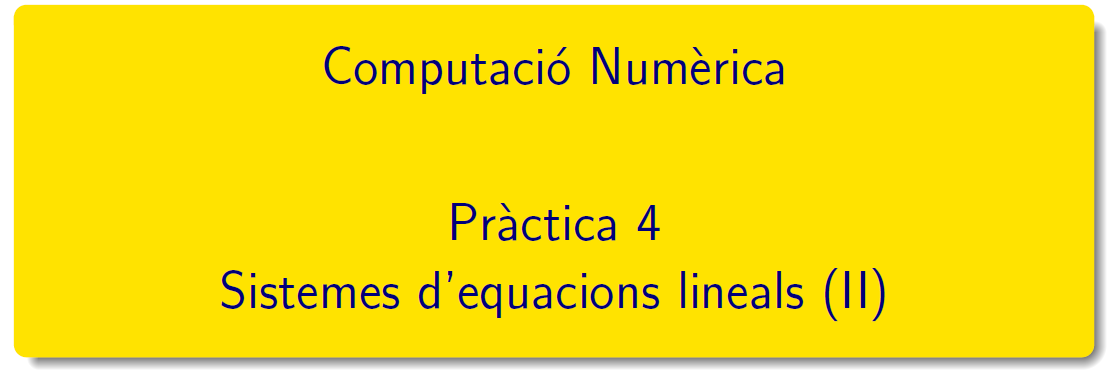

================================================================================

# Pràctica 4 - Mètodes iteratius

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis  en el document CN_full2.pdf, el podeu trobar en el campus virtual. 

**Radi espectral **

Definició i propietats en el document bloc 0 (pàg 16, bloc 0)

Càlcul de valors i vectors propis en Matlab®: consulteu [eigs ](https://www.mathworks.com/help/matlab/ref/eigs.html)i [eig](https://es.mathworks.com/help/matlab/ref/eig.html) 

H = hilb(4)

H =             1          0.5      0.33333         0.25
          0.5      0.33333         0.25          0.2
      0.33333         0.25          0.2      0.16667
         0.25          0.2      0.16667      0.14286


vaps = eig(H), rho = abs(eigs(H,1))  % radi = vap de mòdul màxim

vaps =    9.6702e-05
    0.0067383
      0.16914
       1.5002


rho =        1.5002


[v,d] = eig(H)

v =      0.029193      0.17919     -0.58208      0.79261
     -0.32871     -0.74192       0.3705      0.45192
      0.79141      0.10023      0.50958      0.32242
     -0.51455      0.63828      0.51405      0.25216


d =    9.6702e-05            0            0            0
            0    0.0067383            0            0
            0            0      0.16914            0
            0            0            0       1.5002


## Mètodes iteratius estacionaris 

Són els mètodes de Jacobi, de Gauss-Seidel i de sobrerelaxació (SOR)


$$Ax=b \Longleftrightarrow x^{k+1}=B\,x^{k}+c\,,\quad \forall\ k\ge0\,.$$


### Submatrius D, L i U de la matriu A

 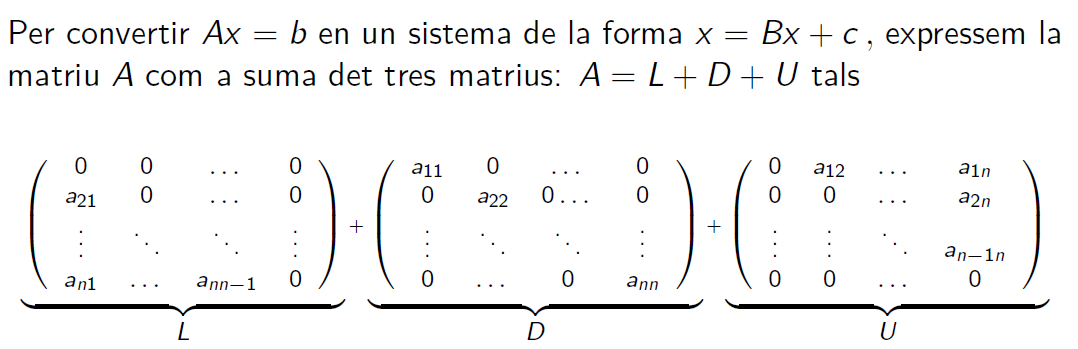     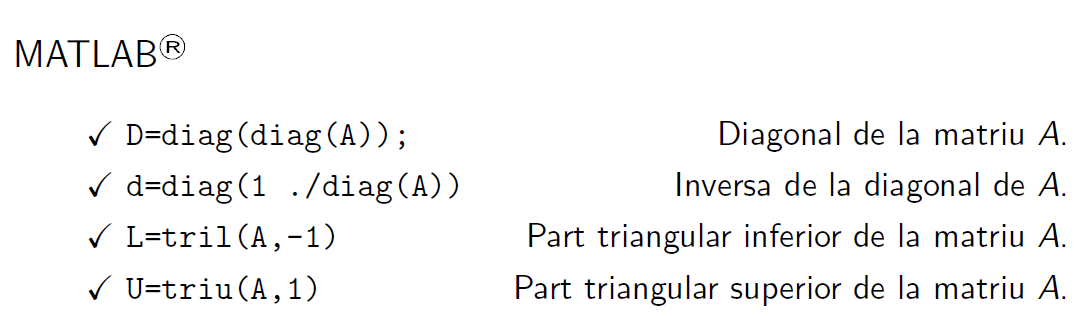

`Exercici 1.`` Obteniu les submatrius L, D, U per a la matriu `$A=\left( \begin{array}{rrr}
1 & 0 & 1 \\
-1 & 1 & 0\\
1 & 2 & -3
\end{array} \right)$

A = [1 0 1; -1 1 0; 1 2 -3]; b=[4;1;-4];
D = diag(diag(A)); L = tril(A,-1); U =triu(A,1); % A-(L+D+U)

#### **Practiquem: Mètodes de Jacobi i de Gauss-Seidel**

`Exercici 2.` `Determineu  les matrius d'iteració del mètode de Jacobi i del mètode de Gauss-Seidel del sistema Ax=b donat per `


$$A=\left( \begin{array}{rrr}
1 & 0 & 1 \\
-1 & 1 & 0\\
1 & 2 & -3
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   4\\ 1\\-4\end{array} \right) 
\quad \Longrightarrow \quad
x=\left(\begin{array}{r}   1\\ 2\\3\end{array} \right) $$


Matrius de Jacobi:  $ x_{Ji}^{(k+1)} = x_i^{(k)} + \displaystyle\frac{1}{a_{ii}}\left( {b_i-\displaystyle \sum_{j=1}^{n}a_{ij}x_j^{(k)}}\right),\quad   k\ge0\,$

d = diag(1./diag(A));
cj = d*b;
Bj =-d*(L+U)

Bj =             0            0           -1
            1            0            0
      0.33333      0.66667            0


Matrius de Gauss-Seidel:  $x_{Si}^{(k+1)} = x_i^{(k)} +\displaystyle \frac{1}{a_{ii}}\left( {b_i-\displaystyle \sum_{j=1}^{i-1}a_{ij}x_j^{(k+1)} -\sum_{j=i+1}^{n}a_{ij}x_j^{(k)}}\right),\quad   k\ge0$

LD = inv(L+D);
cgs = LD*b;
Bgs = -LD*U

Bgs =      0     0    -1
     0     0    -1
     0     0    -1


#### **Practiquem: Mètodes de SOR_Jacobi i de SOR_Gauss-Seidel**

`Exercici 3.` `Determineu  les matrius d'iteració del mètode de SOR_Jacobi i del mètode de SOR_Gauss-Seidel del sistema Ax=b donat per `


$$A=\left( \begin{array}{rrr}
1 & 0 & 1 \\
-1 & 1 & 0\\
1 & 2 & -3
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   4\\ 1\\-4\end{array} \right) 
\quad \Longrightarrow \quad
x=\left(\begin{array}{r}   1\\ 2\\3\end{array} \right) $$


Matrius de SOR-Jacobi:  $ x_{Ji}^{(k+1)} = x_i^{(k)} + \displaystyle\frac{\omega}{a_{ii}}\left( {b_i-\displaystyle \sum_{j=1}^{n}a_{ij}x_j^{(k)}}\right),\quad   k\ge0\,$ i per $\omega$ donat, tal que $0<\omega<2$

A = [1 0 1; -1 1 0; 1 2 -3]; b=[4;1;-4];
D = diag(diag(A)); L = tril(A,-1); U =triu(A,1);
d = diag(1./diag(A));
w = 0.75;
cwj = w*d*b;
Bwj =d*((1-w)*D-w*(L+U))

Bwj =          0.25            0        -0.75
         0.75         0.25            0
         0.25          0.5         0.25


rhowJ=abs(eigs(Bwj,1))   % radi espectral de la matriu del mètode de Gauss-Seidel

rhowJ =       0.83927


Matrius de SOR-Gauss-Seidel: $x_{Si}^{(k+1)} = x_i^{(k)} +\displaystyle \frac{\omega}{a_{ii}}\left( {b_i-\displaystyle \sum_{j=1}^{i-1}a_{ij}x_j^{(k+1)} -\sum_{j=i}^{n}a_{ij}x_j^{(k)}}\right),\quad   k\ge0$  i per $\omega$ donat, tal que $0<\omega<2$

w=1.5

w =           1.5


DI=inv((D+w*L));

cws = w*DI*b;
Bws =DI*((1-w)*D-w*U)

Bws =          -0.5            0         -1.5
        -0.75         -0.5        -2.25
           -1         -0.5         -3.5


rhowS=abs(eigs(Bws,1))   % radi espectral de la matriu del mètode de Gauss-Seidel

rhowS =        4.2417


w òptim

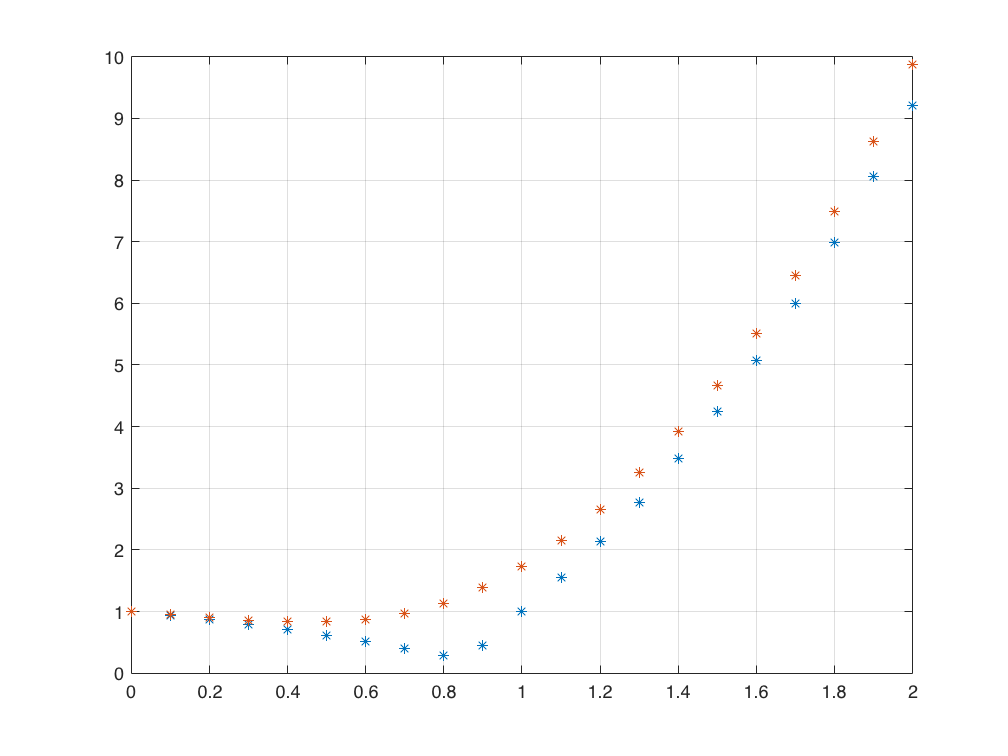

ww=0:0.1:2;
i=0;
for w =ww
    i=1+i;
    DI=inv((D+w*L));
    Bws = DI*((1-w)*D-w*U);
    radis(i) = abs(eigs(Bws,1));
    radis2(i) = norm(Bws,2);
end
plot(ww,radis,'*',ww,radis2,'*'),grid

[r,l]=min(radis)

r =       0.28699


l =      9


ww(l)

ans =           0.8


### Teorema de convergència.

Un esquema iteratiu $x^{k+1}=B\,x^{k}+c\,,\quad \forall\ k\ge0\,$ per a resoldre $Ax=b$ convergeix ssi $\rho(B)<1\,.$

rJ = abs(eigs(Bj,1))

rJ =       0.94444


rhoJ=abs(eigs(Bj,1))   % radi espectral de la matriu del mètode de Jacobi

rhoJ =       0.94444


rhoS=abs(eigs(Bgs,1))   % radi espectral de la matriu del mètode de Gauss-Seidel

rhoS =      1


rhowJ=abs(eigs(BwJ,1))   % radi espectral de la matriu del mètode de Sor-J

rhowJ =       0.67224


#### Exercici 1

Escriviu un programa que implementi els algoritmes de Jacobi, Gauss - Seidel i els mètodes SOR amb paràmetre $\omega$. 

- En una primera aproximació determineu les 10 primeres iteracions dels tres mètodes i estudieu el vector residu per cada mètode. 

- Introduiu un test de convergència per als algoritmes de Jacobi, de Gauss - Seidel i SOR. 

- Proveu-lo per:


$$$$A=\left( \begin{array}{rrrr}
10 & -1 & 2 & 0 \\
-1 & 11 & -1 & 3\\
2 & -1 & 10 & -1\\
0 & 3 & -1 & 8
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   6\\ 25\\-11\\ 15\end{array} \right)
\qquad
x=\left(\begin{array}{r}   1\\ 2\\-1\\ 1\end{array} \right)$$
$$


clearvars
A = [10 -1 2  0; -1 11 -1 3; 2 -1 10 -1; 0 3 -1 8], b=[6;25;-11;15];

A =     10    -1     2     0
    -1    11    -1     3
     2    -1    10    -1
     0     3    -1     8


D = diag(diag(A)); L = tril(A,-1); U =triu(A,1);
X = [1;2;-1;1];

Mètode de Jacobi

d = diag(1./diag(A));
cj = d*b;
Bj =-d*(L+U)

Bj =             0          0.1         -0.2            0
     0.090909            0     0.090909     -0.27273
         -0.2          0.1            0          0.1
            0       -0.375        0.125            0


rhoJ=abs(eigs(Bj,1))   % radi espectral de la matriu del mètode de Jacobi

rhoJ =       0.42644


if rhoJ >=1
    error('mètode de Jacobi divergent')
else
    n=1000; i=0; 
    x = zeros(size(b));
    tol = 0.5e-12
    stop_criteria(1) = 1;
    while(i<n && stop_criteria(max(i,1)) >tol)
        i=i+1;
        y = Bj*x+cj;
        residu(i) = norm(b-A*y,'inf');
        e(i)=norm(y-X,'inf');
        delta(i) = norm(y-x,'inf');
        stop_criteria(i) = delta(i)/norm(y,'inf');
        x=y;
    end
   table(residu',e',delta',stop_criteria','VariableNames',{'residu','e^k','delta^k','stop'})
    x
end

tol =         5e-13


ans = 35×4 table
      residu         e^k         delta^k         stop   
    __________    __________    __________    __________

        7.9182         0.875        2.2727             1
        3.7114       0.28409       0.98977       0.57682
        1.2563       0.13088        0.3374       0.16432
       0.63491      0.046304       0.15704       0.08038
       0.21533      0.021351      0.057719      0.028696
       0.11072     0.0077587      0.026917      0.013511
      0.040002     0.0035943      0.010066      0.005027
      0.019551     0.0013297     0.0047059     0.0023545
      0.007477    0.00061919     0.0017774    0.00088849
     0.0034851    0.00023205    0.00083321    0.00041665
     0.0013839     0.0001085    0.00032252    0.00016125
    0.00062539    4.1037e-05    0.00014883    7.4418e-05
    0.00025455    1.9244e-05    5.9576e-05    2.

x =             1
            2
           -1
            1


format shortG

estudieu $\delta^k/\delta^{k-1}\,.$

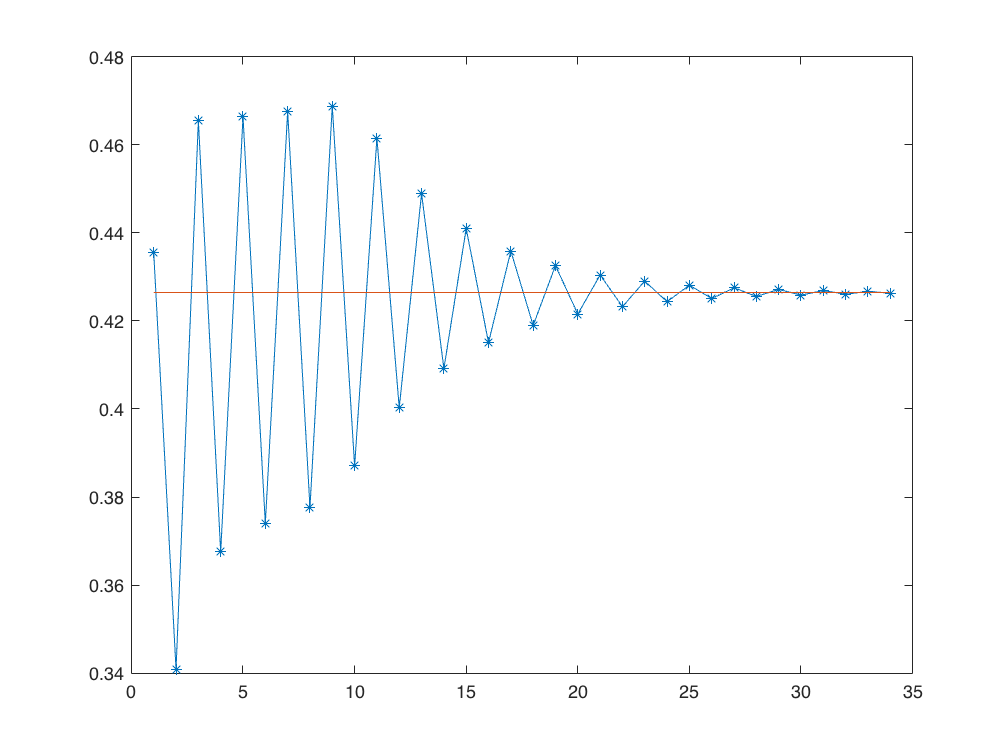

ratio = delta(2:end)./delta(1:end-1);
plot(ratio,'-*'),hold on
plot(rhoJ*ones(size(ratio))), hold off

Mètode de Gauss-Seidel

clear e delta stop_criteria residu
LD = inv(L+D);
cgs = LD*b;
Bgs = -LD*U

Bgs =             0          0.1         -0.2            0
            0    0.0090909     0.072727     -0.27273
            0    -0.019091     0.047273     0.072727
            0   -0.0057955    -0.021364      0.11136


rhoS=abs(eigs(Bgs,1))   % radi espectral de la matriu del mètode de Gauss-Seidel

rhoS =      0.089823


if rhoS >=1
    error('mètode de gauss-seidel divergent')
else
    n=1000; i=0; 
    x = zeros(size(b));
    tol = 0.5e-12
    stop_criteria(1) = 1;
    while(i<n && stop_criteria(max(i,1)) >tol)
        i=i+1;
        y = Bgs*x+cgs;
        residu(i) = norm(b-A*y,'inf');
        e(i)=norm(y-X,'inf');
        delta(i) = norm(y-x,'inf');
        stop_criteria(i) = delta(i)/norm(y,'inf');
        x=y;
    end
   table(residu',e',delta',stop_criteria','VariableNames',{'residu','e^k','delta^k','stop'})
    x
end

tol =         5e-13


ans = 14×4 table
      residu         e^k         delta^k         stop   
    __________    __________    __________    __________

        4.3018           0.4        2.3273             1
       0.34362      0.036938       0.43018       0.21119
      0.057241      0.006585      0.033383      0.016662
      0.007697    0.00086098     0.0057241     0.0028616
    0.00082917     9.128e-05     0.0007697    0.00038485
    7.6973e-05    8.3637e-06    8.2917e-05    4.1458e-05
    6.2206e-06    6.6635e-07    7.6973e-06    3.8487e-06
    4.2234e-07    4.4285e-08    6.2206e-07    3.1103e-07
    2.0648e-08    2.0516e-09    4.2234e-08    2.1117e-08
    1.3883e-09    1.4043e-10    2.0648e-09    1.0324e-09
    1.5724e-10    1.8765e-11     1.257e-10    6.2852e-11
    2.6823e-11    3.0409e-12    1.5724e-11    7.8619e-12
    3.2294e-12    3.5849e-13    2.6824e-12    1.

x =             1
            2
           -1
            1


Mètode de SOR-Jacobi

w = 0.5

w =           0.5


d = diag(1./diag(A)); 
D = diag(diag(A));
cwJ = w*d*b

cwJ =           0.3
       1.1364
        -0.55
       0.9375


BwJ =d*((1-w)*D-w*(L+U))

BwJ =           0.5         0.05         -0.1            0
     0.045455          0.5     0.045455     -0.13636
         -0.1         0.05          0.5         0.05
            0      -0.1875       0.0625          0.5



rJ = abs(eigs(Bj,1))

rJ =       0.42644


if rJ >=1
   error('mètode de Jacobi divergent')
else
    n = 1000; i=0; 
    stop_criteria = 1;
    x = zeros(size(b))
    while (i<n && stop_criteria > 0.5e-12)
        i = i+1;
        y = BwJ*x+cwJ; 
        resJ(i) = norm(b-A*y,'inf');
        dj(i) = norm(x-y,'inf');
        stop_criteria = dj(i)/norm(y,'inf');
        x = y;
    end
    table(resJ',dj','VariableNames',{'residu','d^k'})
fprintf('la solució aproximada per stop_criteria =  %12.8g és x = \n', stop_criteria)
fprintf('%8.5f \n',x)
end

x =      0
     0
     0
     0


ans = 68×2 table
     residu         d^k    
    _________    __________

       9.4375        1.1364
       4.1153       0.42898
       2.1006       0.18706
       1.2533       0.10503
      0.74962      0.062666
      0.47461      0.037481
      0.31439       0.02312
       0.2109      0.016539
      0.14238      0.011563
     0.096404     0.0079798
     0.065353     0.0054641
     0.044313     0.0037228
     0.030039     0.0025279
     0.020352     0.0017127
      0.01378     0.0011584
    0.0093238    0.00078262


la solució aproximada per stop_criteria =  4.3298698e-13 és x = 


 1.00000 
 2.00000 
-1.00000 
 1.00000 


Mètode de SOR - Gauss-Seidel

w = 0.5;
D = diag(diag(A));
DI = inv(D+w*L);
cws = w*DI*b

cws =           0.3
         1.15
      -0.5225
      0.68922


BwS = DI*((1-w)*D-w*U)

BwS =           0.5         0.05         -0.1            0
     0.022727      0.50227     0.040909     -0.13636
    -0.048864     0.020114      0.51205     0.043182
   -0.0073153    -0.092919     0.024332      0.52827


rS = abs(eigs(Bgs,1))

rS =      0.089823


if rS >=1
   error('mètode de Gauss-Seidel divergent')
else
    n = 10; i=0; 
    x = zeros(size(b))
    while i<n
        i = i+1;
        x = BwS*x+cws;
    end
    x
end

x =      0
     0
     0
     0


x =       0.99372
       1.9958
     -0.99593
       1.0043


### **Test de parada **

Fixada una tolerància $\epsilon$ l'algoritme s'ha de parar en la iteració $k$ tal que $||e^{(k)}||=||x-x^{(k)}||<\epsilon$

Com que no coneixem $x$, treballem amb el vector residu: $r^{(k)}=b-Ax^{(k)}$ i apliquem el resultat $\displaystyle\frac{||r^{(k)}||}{||b||}<\epsilon
\Longrightarrow
\frac{||e^{(k)}||}{||x||}<\epsilon\,cond(A)$

#### Exercici 2

Introduiu un test de convergència per als algoritmes de Jacobi, de Gauss - Seidel i SOR. Proveu-lo per

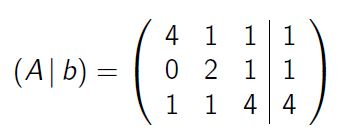     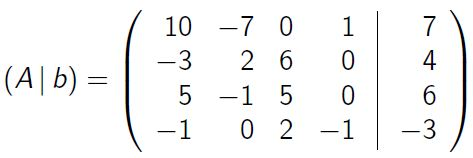      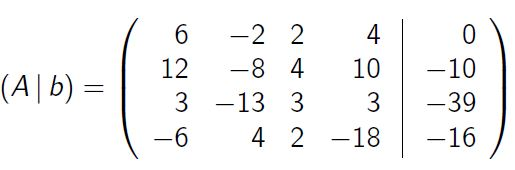

A = [4 1 1; 0 2 1; 1 1 4], b = [1;1;4]; 

A =      4     1     1
     0     2     1
     1     1     4


% Per fer...

A = [10 -7 0 1;-3 2 6 0; 5 -1 5 0; -1 0 2 -1], b = [7;4;6;-3]; 

A =     10    -7     0     1
    -3     2     6     0
     5    -1     5     0
    -1     0     2    -1


% Per fer...

A = [6 -2 2 4; 12 -8 4 10; 3 -13 3 3; -6 4 2 -18], b = [0; -10; -39; -16]; 

A =      6    -2     2     4
    12    -8     4    10
     3   -13     3     3
    -6     4     2   -18


% Per fer...


### Practiquem ...

#### Exercici 3

Resoleu pel mètode de Jacobi i de Gauss-Seidel el sistema $Ax=b$ donat per


$$A=\left( \begin{array}{rrrr}
	10 & -1 & 2 & 0 \\
	-1 & 11 & -1 & 3\\
	2 & -1 & 10 & -1\\
	0 & 3 & -1 & 8
	\end{array} \right)\quad\quad
	b=\left(\begin{array}{r}   6\\ 25\\-11\\ 15\end{array} \right)$$


prenent $x^{(0)}=(0\,,0\,,0\,,0)^{\top}$ i una tolerància $\epsilon = 0.5\cdot 10^{-12}$. Quantes iteracions calen?

Calculeu els errors $\delta^k = ||x^k-x^{k-1}||$ i estudieu $\delta^k/\delta^{k-1}\,.$

% Per fer ... resultats -> exercici3_tema2.html
A = [10 -1 2  0; -1  11 -1 3; 2 -1 10 -1; 0 3 -1 8];
b = [6;25;-11;15];
Bj=-d*(L+U);
cj=d*b;
rJ = abs(eigs(Bj,1))

rJ =       0.42644



if rJ >=1
   error('mètode de Jacobi divergent')
else
    n = 1000; i=0; 
    stop_criteria = 1;
    x = zeros(size(b))
    while (i<n && stop_criteria > 0.5e-12)
        i = i+1;
        y = Bj*x+cj; 
        resJ(i) = norm(b-A*y,'inf');
        dj(i) = norm(x-y,'inf');
        stop_criteria = dj(i)/norm(y,'inf');
        x = y;
    end
    table(resJ',dj','VariableNames',{'residu','d^k'})
fprintf('la solució aproximada per stop_criteria =  %12.8g és x = \n', stop_criteria)
fprintf('%8.5f \n',x)
end

x =      0
     0
     0
     0


ans = 68×2 table
      residu         d^k    
    __________    __________

        7.9182        2.2727
        3.7114       0.98977
        1.2563        0.3374
       0.63491       0.15704
       0.21533      0.057719
       0.11072      0.026917
      0.040002      0.010066
      0.019551     0.0047059
      0.007477     0.0017774
     0.0034851    0.00083321
     0.0013839    0.00032252
    0.00062539    0.00014883
    0.00025455    5.9576e-05
    0.00011273    2.6746e-05
    4.6632e-05    1.0944e-05
    2.0382e-05    4.8259e-06


la solució aproximada per stop_criteria =  2.2043478e-13 és x = 


 1.00000 
 2.00000 
-1.00000 
 1.00000 


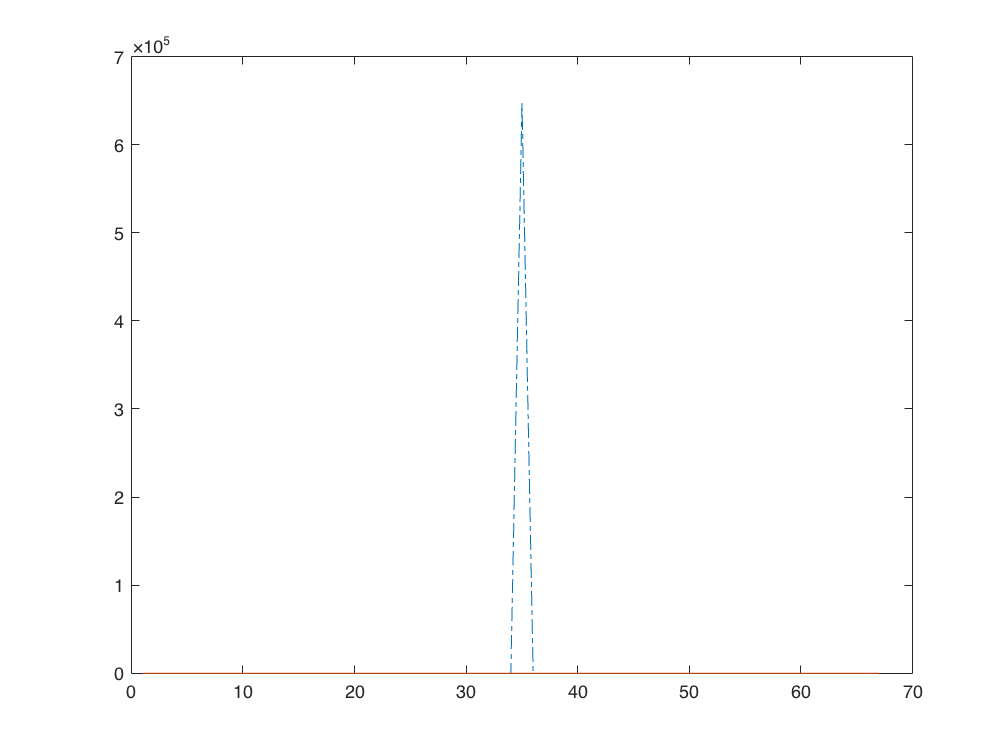


ratio = dj(2:end)./dj(1:end-1);
K = length(ratio);
plot(1:K,ratio,'-.',1:K,rJ*ones(size(ratio)))


rJ*ones(size(ratio))

ans =       0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644      0.42644


#### Exercici 4

Determineu el factor $\omega$ per a resoldre


$$\left\{ \begin{array}{rcrcrcrcr}
		10x & + & 5y &  &   &   &    & = & 6\\ %[-0.3em]
		5x & + & 10y &- & 4z &   &   & = & 25\\ %[-0.3em]
	 	   & - & 4y & + & 8z  & - & t  & = & -11\\ %[-0.3em]
		   &  &   & - & z & + & 5t  & = & -11
	\end{array}\right.$$


fent ús dels mètodes de sobrerelaxació variants de Jacobi i de Gauss-Seidel. 

Feu un estudi per $0<\omega<2$. Presenteu els resultats en una taula.

% Per fer ... resultats -> exercici4.html
A = [10 5 0 0; 5 10 -4 0; 0 -4 8 -1; 0 0 -1 5]

A =     10     5     0     0
     5    10    -4     0
     0    -4     8    -1
     0     0    -1     5


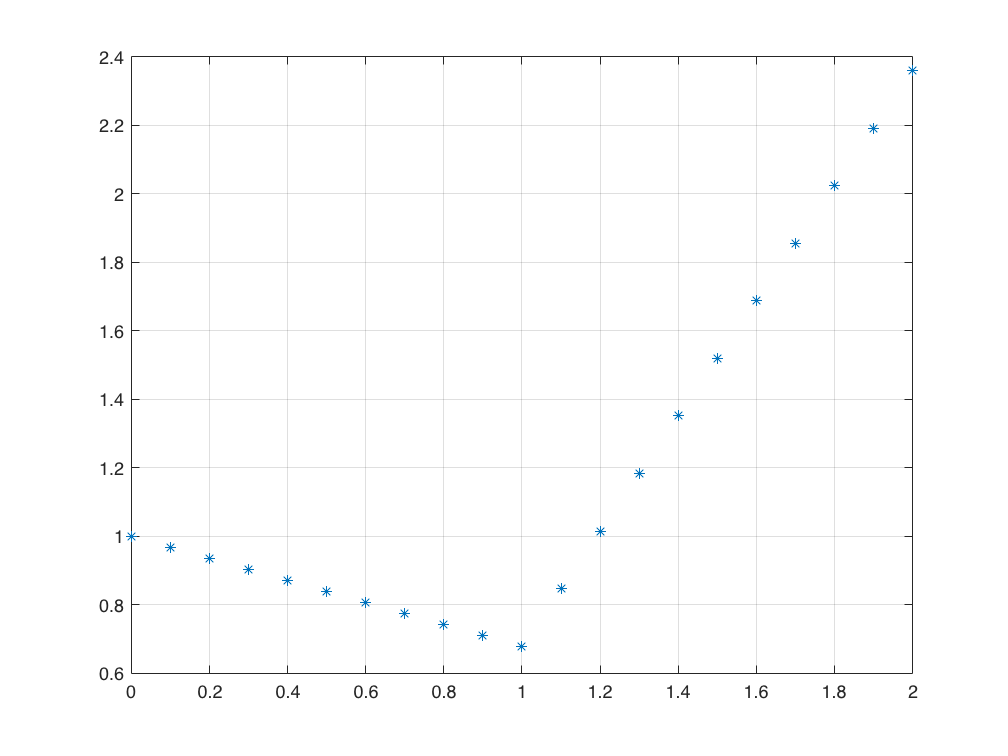

b = [6; 25; -11; -11]; 
D = diag(diag(A));
L=tril(A,-1); U = triu(A,1);

d = diag(1./diag(A)); 
D = diag(diag(A));
% cwJ = w*d*b;
ww = 0:0.1:2;
j=0;
for w=ww
    j=j+1;
    BwJ =d*((1-w)*D-w*(L+U));
    rwJ(j) = abs(eigs(BwJ,1));   % valor un cop fixat w
end
plot(ww,rwJ,'*'),grid

[r,i] = min(rwJ)

r =       0.67931


i =     11


ww(i)

ans =      1


Resoleu pels mètodes de classe el sistema $Ax=b$ donat per 


$$A=\left( \begin{array}{rrrr}
		15 & -5 &  0 & -5\\
		-5 & 12 & -2 &  0\\
		0 & -2 &  6 & -2\\
		-5 &  0 & -2 &  9
	\end{array} \right)\quad
	b=\left(\begin{array}{r}   -3.45\\ 9.96\\0\\ 0\end{array} \right)\quad
	x^{*}=\left(\begin{array}{c}   0.14\\ 0.95\\0.37\\ 0.16\end{array} \right)$$


prenent $x^{(0)}=(0\,,0\,,0\,,0)^{\top}$ i una tolerància Quantes iteracions calen?

Calculeu els errors $e^k = ||x^k-x^{\ast}||$,   $\delta^k = ||x^k-x^{k-1}||$ i estudieu $e^k/e^{k-1}\,,\quad$  $\delta^k/\delta^{k-1}\,.$ 

% Per fer ... resultats -> exercici5.html
clearvars
A = [15 -5 0 -5; -5 12 -2 0; 0 -2 6 -2; -5 0 -2 9];
b = [-3.45;9.96;0;0]; y = [0.14;0.95;0.37;0.16]; 
L=tril(A,-1), U = triu(A,1) % A-(L+D+U)

L =      0     0     0     0
    -5     0     0     0
     0    -2     0     0
    -5     0    -2     0


U =      0    -5     0    -5
     0     0    -2     0
     0     0     0    -2
     0     0     0     0



w = 0.5;
D = diag(diag(A));
DI = inv(D+w*L);
Bgs=-DI*U;
rS = abs(eigs(Bgs,1))

rS =       0.27672


cws = w*DI*b

cws =        -0.115
      0.39104
     0.065174
    -0.024703


BwS = DI*((1-w)*D-w*U)

BwS =           0.5      0.16667            0      0.16667
      0.10417      0.53472     0.083333     0.034722
     0.017361      0.08912      0.51389      0.17245
      0.14082     0.056199     0.057099      0.56546



if rS >=1
   error('mètode de Gauss-Seidel divergent')
else
    n = 10; i=0; 
    x = zeros(size(b))
    while i<n
        i = i+1;
        x = BwS*x+cws;
    end
    x
end

x =      0
     0
     0
     0


x =      0.092423
      0.91143
      0.32719
      0.11265


## Mètodes iteratius no estacionaris 

Consulteu en la documentació de MATLAB® - [Iterative Methods for Linear Systems](https://es.mathworks.com/help/matlab/math/iterative-methods-for-linear-systems.html)

`Document preparat per M. Àngela Grau Gotés, 8 de març de 2022`